# Set up strategies

data = (1:4)'; %each sample is a row (like a database row)
lr = 0.001;

tic;
alice = [0.99, 0.99, 0.01, 0.01];
bob = [0.01, 0.99, 0.01, 0.99];
numSamples = size(data, 1);

jDist = zeros(2,2);

## Compute joint distribution

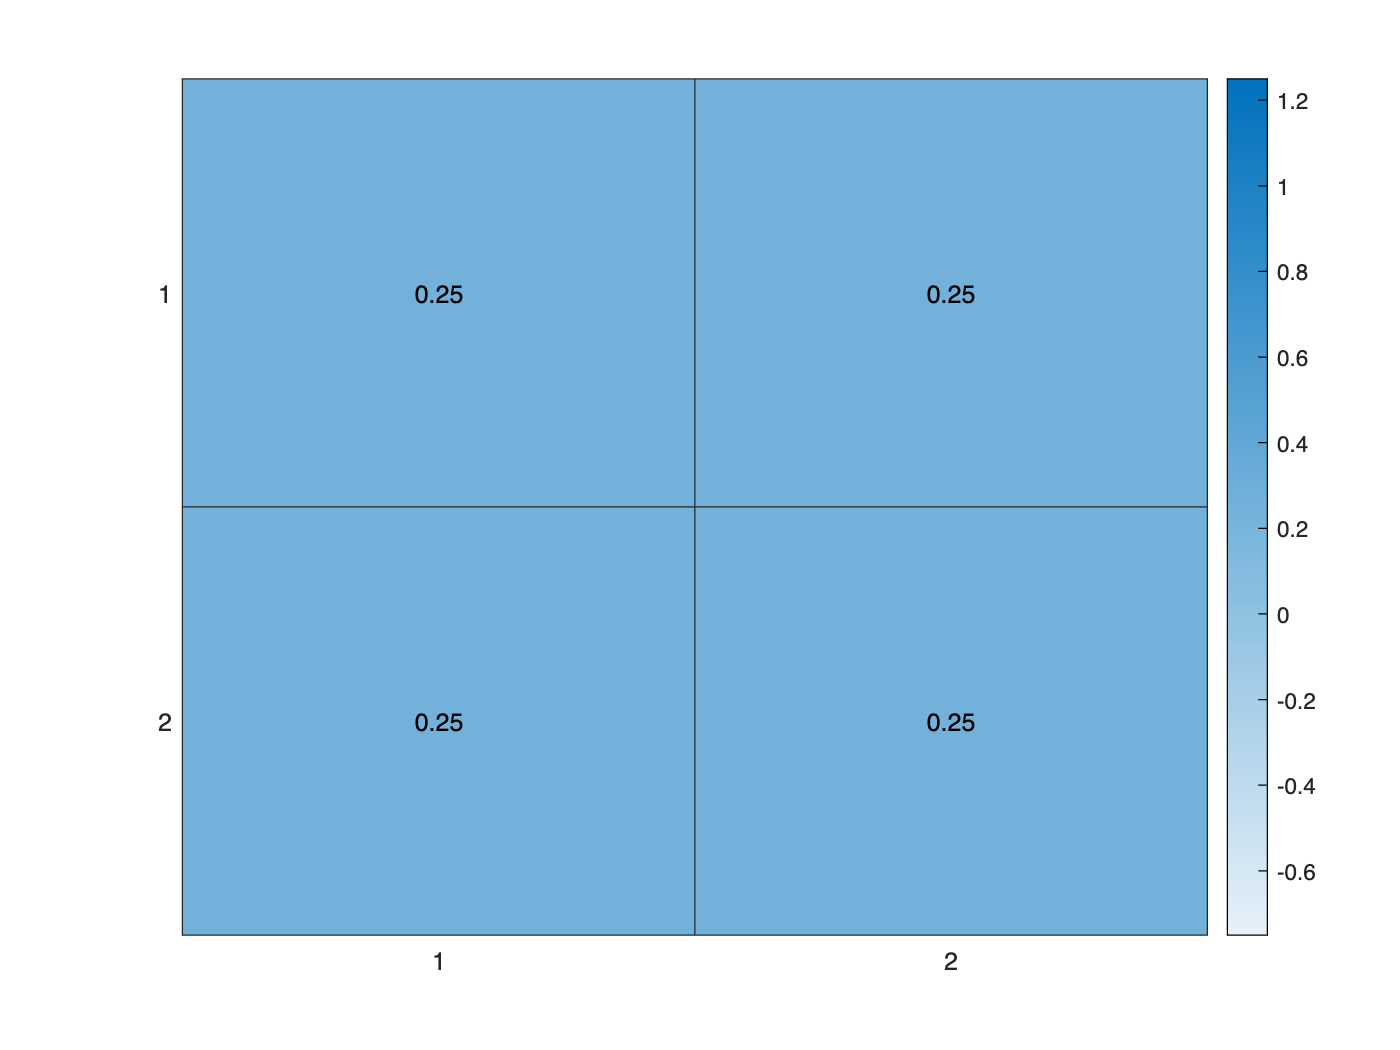

for sampleInd = 1:numSamples
    s = data(sampleInd,:);
    sampleJoint = [alice(s)*bob(s), alice(s)*(1-bob(s));
                         (1-alice(s))*bob(s), (1-alice(s))*(1-bob(s))];
    jDist = jDist  + sampleJoint / numSamples;
end
heatmap(jDist)

## Compute average coding inefficiencies

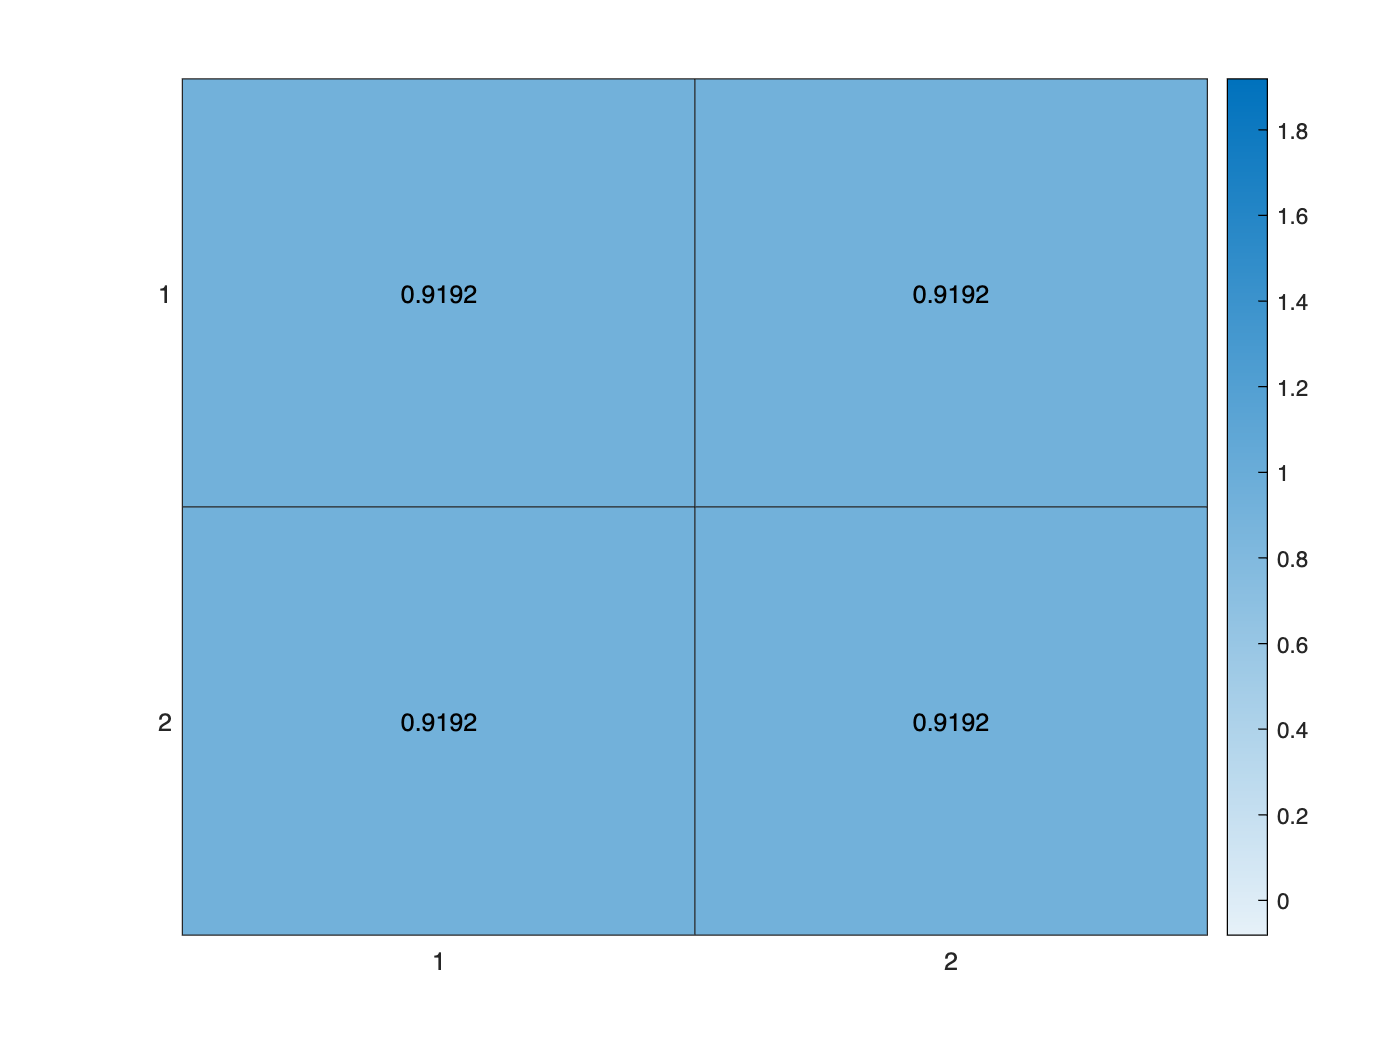

averageInefficiencies = zeros(2,2);
% alice unconditional entropy
pA = sum(jDist,2);
pA = pA(1);
% bob unconditional entropy
pB = sum(jDist, 1);
pB = pB(1);

for sampleInd = 1:numSamples
    s = data(sampleInd,:);
    pASamp = alice(s);
    pBSamp = bob(s);

    % Conditional probabilities
    pACondB = jDist * [pBSamp; 1-pBSamp];
    pACondB  = pACondB  / sum(pACondB);
    pACondB = pACondB(1);
    pBCondA = [pASamp 1-pASamp] * jDist;
    pBCondA = pBCondA / sum(pBCondA);
    pBCondA = pBCondA(1);

    sampleIneffs = [codingInefficiency(pASamp, pA) codingInefficiency(pASamp, pACondB);
                    codingInefficiency(pBSamp, pBCondA) codingInefficiency(pBSamp, pB)];
    
    averageInefficiencies = averageInefficiencies + sampleIneffs/numSamples;

end
heatmap(averageInefficiencies)

function [ineff] = codingInefficiency(trueProb, codingProb)
    ineff = - (trueProb*logcl(codingProb) + (1-trueProb)*logcl(1-codingProb)) - binent(trueProb);
end

function [ent] = binent(p)
    if p == 0
        ent = 0;
        return;
    end
    ent = - (p.*logcl(p) + (1-p).*logcl(1-p));
end

function [y] = logcl(x)
    mask = x<=0;
    y = log2(x);
    y(mask) = 0;
end
